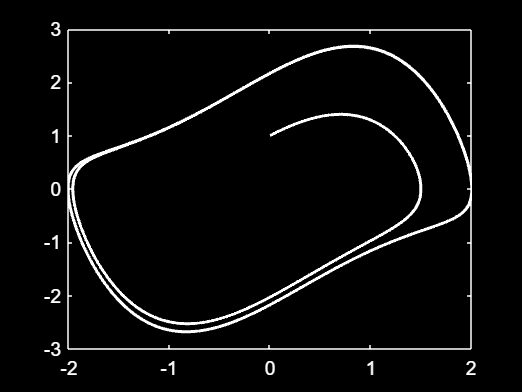

clear all; close all; clc;

mu = 1; % hopf bifn at mu = 0
x0 = [0; 1]; % initial condition
dt = 0.001; % times step
timeSpan = dt:dt:50; % time span

% set otions to alow for more accurate simulation and control of error tolerances
% set relative tolerance to 10^-12 and absoute tolerence of each component
% to the 10^-12
options = odeset('RelTol',1e-12, 'AbsTol',1e-12*ones(1,2));

% output is time and the time history of state x
% wrap vdp function as function of x and t for ode45
% ode 45 wants time variable even though our DE is not time dependedent
[t,x] = ode45(@(t,x) vanderpol(t,x,mu), timeSpan, x0, options);

plot(x(:,1), x(:,2), 'w', 'LineWidth', 1.5);
set(gca, 'color','k', 'xcolor','w', 'ycolor','w');
set(gcf, 'color','k');